# Getting Started with The KST toolbox 

Toolbox authors:  Andrea Brancaccio, Luca Stefanutti &  Debora de Chiusole

Other toolbox references: Brancaccio A., de Chiusole D., Wickelmaier  F. (2024). Software. In Heller J. & Stefanutti L. *Knowledge structures Recent developments in Theory and Application. *Vol. 7. World Scientific. [https://doi.org/10.1142/13519](https://doi.org/10.1142/13519)

## Description

The toolbox is structured around essential functions that serve the following purposes:

- Building and Visualizing Knowledge Structures: Includes functions for creating and visualizing knowledge structures.

- Simulating and Fitting the BLIM: Utilizes the Expectation-Maximization algorithm (Stefanutti & Robusto, 2009) to simulate and fit the basic local indipendence model  (BLIM) by maximum likelihood. This can be done with both complete and missing-at-random data (Anselmi et al., 2016; de Chiusole et al., 2015).

- Simulating and Fitting the Constrained-BLIM: Introduces functions for simulating and fitting the constrained-BLIM (de Chiusole et al., 2018). This is particularly useful for testing item equality at the deterministic and/or probabilistic level.

- Identifiability Testing of the BLIM: Incorporates the blimit function (Stefanutti et al., 2012) for testing the identifiability of the BLIM.

## System Requirements

The toolbox requires MATLAB. Compatibility tested for versions from 2020a on.

## Examples

Examples of the application of the main features of the toolbox.

### Example on fraction dataset 

Example based on the thirteen items presented in Stefanutti and de Chiusole (2017).

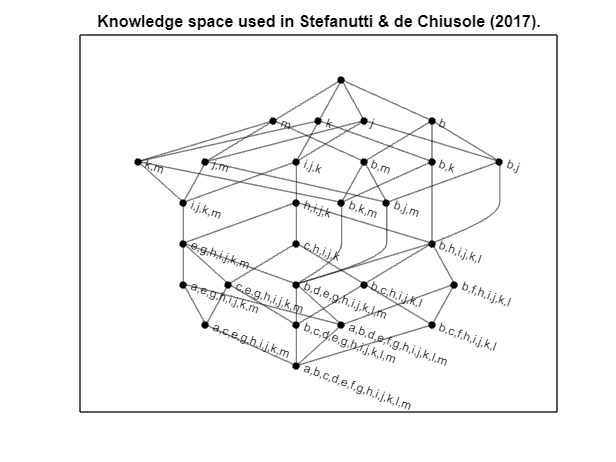

%%Load the skillmap "map" and the data for the thirteen items presented in Stefanutti and de Chiusole (2017)
load('data_fraction.mat')

% definition of the knowledge space using function skillmap, there is a mapping one to one between
% rows of kspace and rows of cspace 
[kspace,cspace,itemindex]=skillmap(map);
% kspace contains the knowledge states replicate to match the competence states in cspaces
states=unique(kspace,"rows");

% Plotting the the knowledge strucure with the four different default labels
figure(1)
plot_knowledge_structure(states,'literals');
title("Knowledge space used in Stefanutti & de Chiusole (2017).")

%Estimating the BLIM 
nrep_gm=50;
nrep_bootstrap=500;
options.feedback=50;
[best_model1]=blimfit(data,states,nrep_gm,nrep_bootstrap,[],options);


Local minima checking...
Proportion of replication 100%
*** Basic Local Independence Model ***
Title: BLIM Maximum Likelihood via Expectation Maximization

Reference: Stefanutti & Robusto (2009)

Knolwedge structure
	Number of items:               13
	Number of knowledge states:    28

Sample
	Number of observations:         191
	Number of response patterns:    115

Algorithm: EM
	Convergence criterion (parameters):0.000010
	Number of maximum iterations:   1000
	Actual iteration:              141

The algorithm terminates after reaching the tolerance value

Fit of the model:
	Chi-Squared:                  20340.11
	Degrees of freedom:             8138
	Bootstrapped p-value           0.018782
	Bootstrap replications         500

Comparison with the Saturated Model:
	Loglikelihood of the model:    -1186.06
	Likelihood ratio:             752.25
	Bootstrapped p-value           0.000000
	Bootstrap replications         500


Parameter estimates

class item         beta          eta
    1   

### Example on Descriptive Statisitcs

Example based on the 24 items presented in de Chiusole et al. (2018).

% loading the data and the skill function
load dataSD.mat
load skill_functionSD.mat
% delineating the knowledge structures and removing repetitions
states = skillmap(mapfit);
states = unique(states, 'rows');
% preparing the matrix of the equivalence classes
nclasses = size(datafit, 2);
nq = nclasses/2;
classes = zeros(nq, nclasses);
% automatic generation of the classes matrix
for i = 1:size(classes, 1)
    if i < 2
        classes(i, i) = 1;
        classes(i, i+1) = 1;
    else
        classes(i, i*2-1) = 1;
        classes(i, i*2) = 1;
    end
end
% estimating the BLIM with equality constraints
nrep_gm = 50;
nrep_boot = 500;
best_model = blimfit(datafit, states, nrep_gm, nrep_boot, classes);


Local minima checking...
Maximum number of iterations exceeded in BLIM
Maximum number of iterations exceeded in BLIM

The likelihood ratio (LR) test will not be compute
Increase the options.nitems argument to compute the LR test

Proportion of replication 100%
*** Basic Local Independence Model ***
Title: Costrainted-BLIM Maximum Likelihood via Expectation Maximization with Missing-at-Random

Reference: de Chiusole, D., Stefanutti, L., Anselmi, P., & Robusto, E. (2018).

Knolwedge structure
	Number of items:               24
	Number of knowledge states:    165

Sample
	Number of observations:         286
	Number of response patterns:    281

Algorithm: EM
	Convergence criterion (parameters):0.000010
	Number of maximum iterations:   1000
	Actual iteration:              130

The algorithm terminates after reaching the tolerance value

Fit of the model:
	Chi-Squared:                  508896370.73
	Degrees of freedom:             16777027
	Bootstrapped p-value           0.012670
	Bootstra

printmodel(best_model);


*** Basic Local Independence Model ***
Title: Costrainted-BLIM Maximum Likelihood via Expectation Maximization with Missing-at-Random

Reference: de Chiusole, D., Stefanutti, L., Anselmi, P., & Robusto, E. (2018).

Knolwedge structure
	Number of items:               24
	Number of knowledge states:    165

Sample
	Number of observations:         286
	Number of response patterns:    281

Algorithm: EM
	Convergence criterion (parameters):0.000010
	Number of maximum iterations:   1000
	Actual iteration:              130

The algorithm terminates after reaching the tolerance value

Fit of the model:
	Chi-Squared:                  508896370.73
	Degrees of freedom:             16777027
	Bootstrapped p-value           0.012670
	Bootstrap replications         500


Parameter estimates

class item         beta          eta
    1    1     0.070861     0.196927
    1    2     0.070861     0.196927
    2    3     0.072112     0.067617
    2    4     0.072112     0.067617
    3    5     0.205288   

## References

Anselmi, P., Robusto, E., Stefanutti, L., & de Chiusole, D. (2016). An upgrading procedure for adaptive assessment of knowledge. *Psychometrika*, *81*, 461-482.

de Chiusole, D., Stefanutti, L., Anselmi, P., & Robusto, E. (2015). Modeling missing data in knowledge space theory. *Psychological Methods*, *20*(4), 506.

de Chiusole, D., Stefanutti, L., Anselmi, P., & Robusto, E. (2018). Testing the actual equivalence of automatically generated items. *Behavior Research Methods*, *50*, 39-56.

Stefanutti, L., & de Chiusole, D. (2017). On the assessment of learning in competence based knowledge space theory. *Journal of Mathematical Psychology*, *80*, 22-32.

Stefanutti, L., Heller, J., Anselmi, P., & Robusto, E. (2012). Assessing the local identifiability of probabilistic knowledge structures. *Behavior Research Methods*, *44*, 1197-1211.

Stefanutti, L., & Robusto, E. (2009). Recovering a probabilistic knowledge structure by constraining its parameter space. *Psychometrika*, *74*, 83-96.